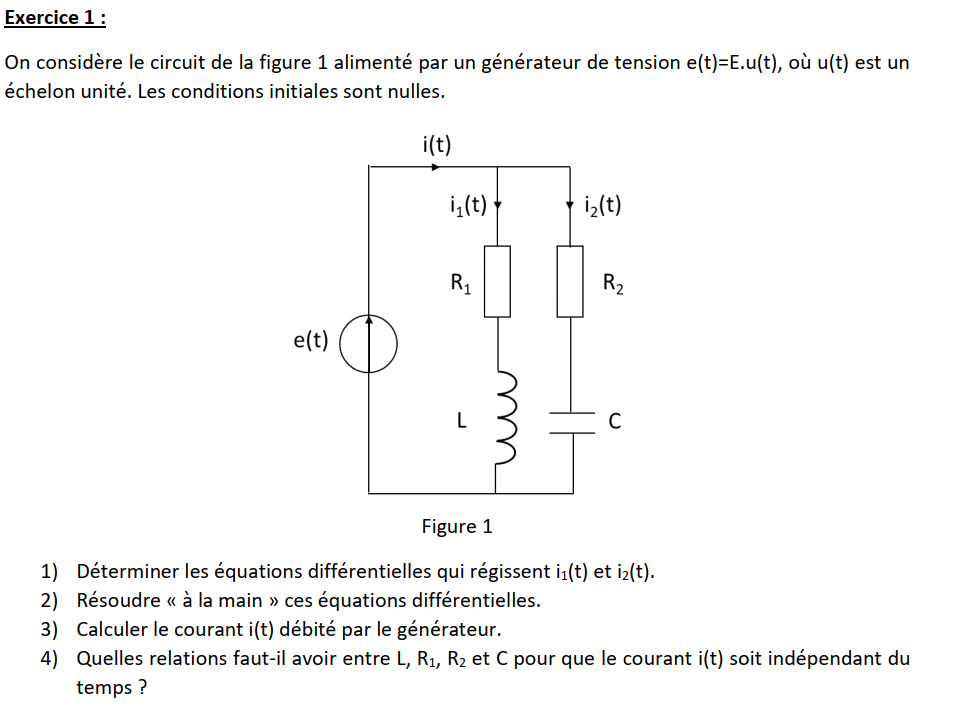

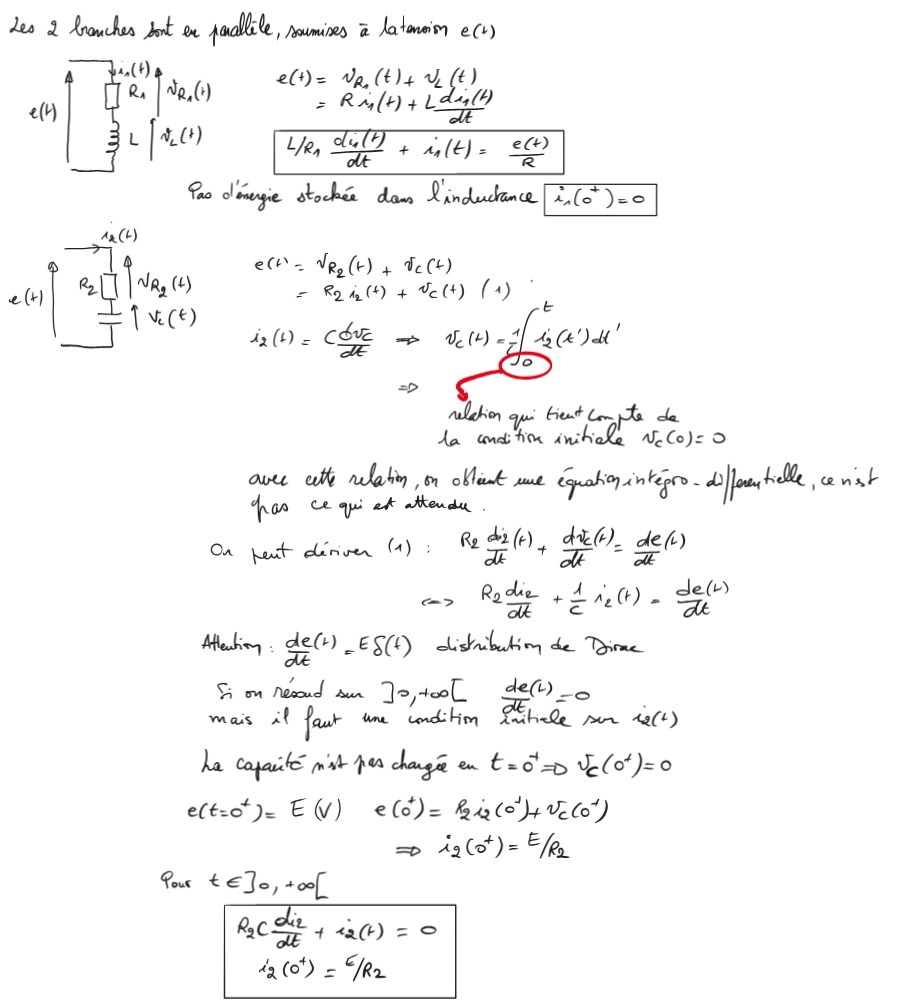

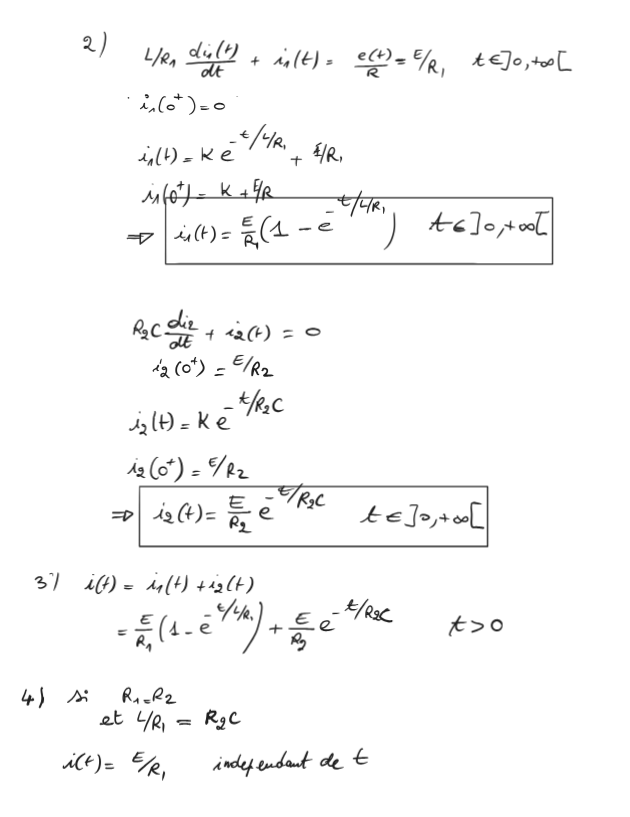

Résolution des équations différentielles avec Matlab :

syms R1 R2 C L E i1(t) i2(t) t
i1=dsolve(L/R1*diff(i1,t)+i1(t)==E/R1,i1(0)==0)

$$i1 = \frac{\text{E}-\text{E}\,{\mathrm{e}}^{-\frac{R_{1}\,t}{L}}}{R_{1}}$$

i2=dsolve(R2*C*diff(i2,t)+i2(t)==0,i2(0)==E/R2)

$$i2 = \frac{\text{E}\,{\mathrm{e}}^{-\frac{t}{C\,R_{2}}}}{R_{2}}$$

Tracé des courbes

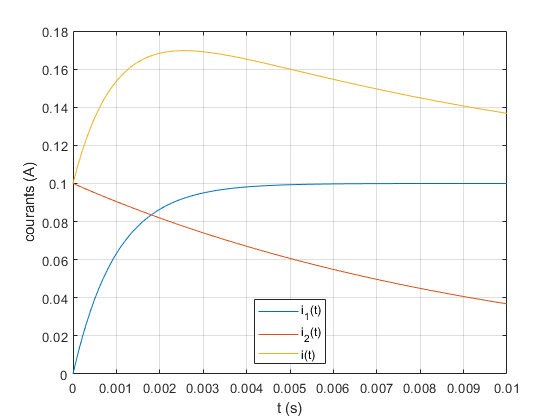

R1=100;R2=100;C=100e-6;L=0.1;E=10;
t=linspace(0,10e-3,100);
figure
plot(t,subs(i1),t,subs(i2),t,subs(i1+i2))
xlabel('t (s)');ylabel('courants (A)');legend('i_1(t)','i_2(t)','i(t)','location','best');grid

Le courant $i(t)$ est indépendant de $t$ si $\frac{L}{R_1}=R_2C$ et $R_1=R_2$. Cette condition est réalisée avec $L=R_1R_2C=100^2\times 100 \times  10^{-6}=1\ \rm H$

L=100^2*100e-6

L = 1

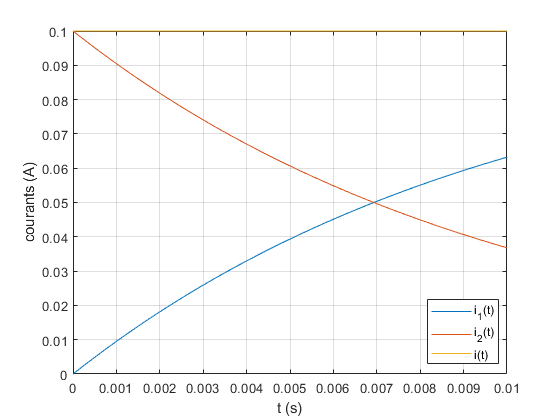

figure
plot(t,subs(i1),t,subs(i2),t,subs(i1+i2))
xlabel('t (s)');ylabel('courants (A)');legend('i_1(t)','i_2(t)','i(t)','location','best');grid

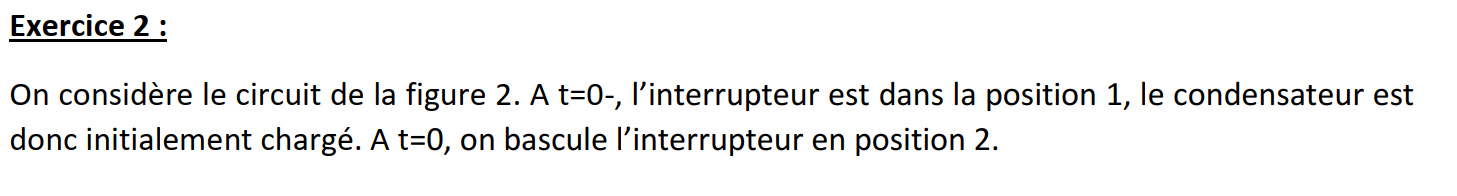

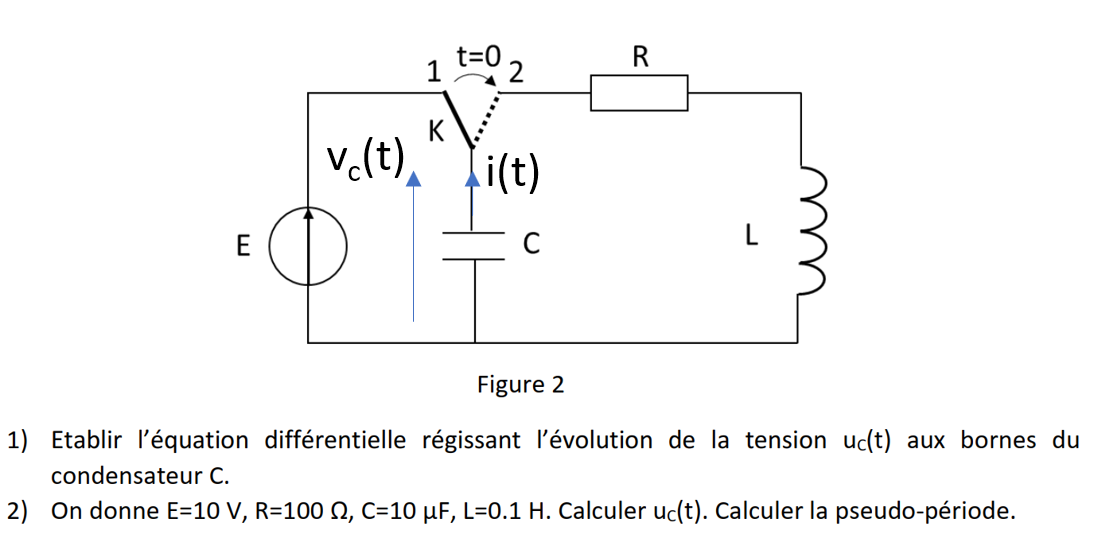

1 / A t=0 $v_c(t)=Ri(t)+L\frac{di}{dt}(t)$

En utilisant $i(t)=-C\frac{dv_c}{dt}(t)$, on obtient :

$LC\frac{d^2v_c}{dt^2}(t)+RC\frac{dv_c}{dt}(t)+v_c(t)=0$ avec $v_c(0)=E$et $i(0)=-C\frac{dv_c}{dt}(0)=0$

2 / Application numerique :

$LC=10^{-6}\ s^$, $RC=10^{-3}\ s$.


$$10^{-6}\frac{d^2v_c}{dt^2}(t)+10^{-3}\frac{dv_c}{dt}(t)+v_c(t)=0$$


Solution homogène : 


$$10^{-6}r^2+10^{-3}r+1=0$$



$$\Delta=(10^{-3})^2-4\times 10^{-6}=-3\ 10^{-6}$$



$$r_{1,2}=\frac{-10^{-3} \pm \sqrt{-3 10^{-6}}}{2\times 10^{-6}}=-500\pm j866$$



$$v_c(t)=e^{-500t}\left(A\ cos(866t)+B\ sin(866t)\right)$$



$$v_c(0)=E \Longrightarrow A=E=10$$



$$\frac{dv_c}{dt}(t)=-500\ e^{-500t}Ecos(866t)-866e^{-500t}Esin(866t)+-500
\ e^{-500t}Bsin(866t)+866e^{-500t}Bcos(866t)$$



$$\frac{dv_c}{dt}(0)=0=-500E+866B \Longrightarrow B=5.77$$



$$v_c(t)=10\times e^{-500t}cos(866t)+5.77e^{-500t}sin(866t)$$


La pseudo période est $T=\frac{2\pi}{866}=7.3 \rm \ ms$

syms vc(t)
Dvc=diff(vc)

$$Dvc(t) = \frac{\partial }{\partial t}\mathrm{vc}\left(t\right)$$

vc=dsolve(1e-6*diff(vc,t,2)+1e-3*diff(vc,t)+vc,vc(0)==10,Dvc(0)==0)

$$vc = \frac{10\,{\mathrm{e}}^{-500\,t}\,\left(3\,\cos\left(500\,\sqrt{3}\,t\right)+\sqrt{3}\,\sin\left(500\,\sqrt{3}\,t\right)\right)}{3}$$

vpa(vc,2)

$$ans = 3.3\,{\mathrm{e}}^{-500.0\,t}\,\left(3.0\,\cos\left(870.0\,t\right)+1.7\,\sin\left(870.0\,t\right)\right)$$

vpa(expand(ans),3)

$$ans = 10.0\,{\mathrm{e}}^{-500.0\,t}\,\cos\left(866.0\,t\right)+5.77\,{\mathrm{e}}^{-500.0\,t}\,\sin\left(866.0\,t\right)$$

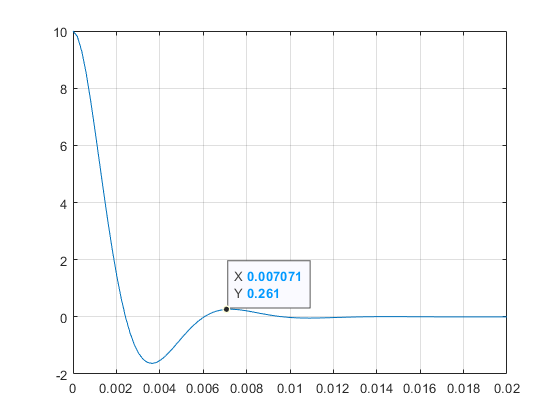

figure
t=linspace(0,20e-3,100);
plot(t,subs(vc))
grid

ax = gca;
chart = ax.Children(1);
datatip(chart,0.007071,0.261);

Avec le curseur, on retrouve une pseudo période de 7 ms.